# initialize breach. Every breach driver script will typically start with

InitBreach;

clc;
clear S;
close all;

## Initialize the values of various parameters appearing in this model.

feel free to change the values of these parameters and experiment with them.

% Initial position of the host car 
x0_host = 0; % (m)

% Initial velocity of the host car
v0_host = 10; % (m/s)

% Initial position of the lead car. Take care to initialize the lead car
% at least dSafe distance away from the host car!
x0_lead = 50; % (m)
 
% Initial velocity of the lead car.
v0_lead = 20; % (m/s)

% Cruising speed reference set by the host-car driver
vref_host = 20; % (m/s)

% sample time for this model. Using smaller sample times will lead to
% slower simulations. 
Ts = 0.5; % (seconds)

% the simulation time horizon, we will run each simulation for endTime secs
endTime = 50; % (seconds)

% Minimum safe distance that ACC is required to maintain between the host
% car and the lead car
dSafe = 2; % (m)

% maximum acceleration possible for the lead car
leadAccMax = 2; % (m/s^2)

% minimum acceleration possible for the lead car
leadAccMin = -1; % (m/s^2)


% Create an interface to the ACC_HW simulink model from Breach
S = BreachSimulinkSystem('ACC_HW');

Found var Ts in base workspace used by ACC_HW_breach.
Found var dSafe in base workspace used by ACC_HW_breach/Adaptive Cruise Control System/Constant.
Found var v0_host in base workspace used by ACC_HW_breach/Constant.
Found var v0_lead in base workspace used by ACC_HW_breach/Constant3.
Found var vref_host in base workspace used by ACC_HW_breach/Set velocity.
Found var x0_host in base workspace used by ACC_HW_breach/Constant1.
Found var x0_lead in base workspace used by ACC_HW_breach/Constant2.



% The times at which we wish to observe system behavior 
tspan = 0:Ts:endTime;

% Through this command, Breach tells Simulink to provide trajectories at 
% each point in the tspan vector
S.SetTime(tspan);

% the following commands create a parameterized input signal. The 
% parameterization of the input is done such that the resulting signal
% has numCP equally spaced control points, i.e., the signal is assumed 
% to change only at the times specified by the control points 
% and remains constant between control points. 
numCP = 20;
inputGen.type = 'UniStep';
inputGen.cp = numCP;
S.SetInputGen(inputGen);

% the above commands created numCP parameters for each input signal in the 
% simulink model. Below we create a cell array containing a list of these
% parameters. We hard-code the string 'LeadAcc' here as that is the name of
% the only input signal in this model
params = cell(1,numCP);
for jj=1:numCP
   params{1,jj} = sprintf('LeadAcc_u%d',jj-1);
end

% specify that at each control point, the input signal can be some value
% between [leadAccMin, leadAccMax]
S.SetParamRanges(params,repmat([leadAccMin leadAccMax],numCP,1));

% inspect all the parameters that breach allows us to manipulate
S.PrintParams;

-- PARAMETERS --
Ts=0.5       
dSafe=2       
v0_host=10       
v0_lead=20       
vref_host=20       
x0_host=0       
x0_lead=50       
LeadAcc_u0=0       of type double in [-1, 2]
LeadAcc_u1=0       of type double in [-1, 2]
LeadAcc_u2=0       of type double in [-1, 2]
LeadAcc_u3=0       of type double in [-1, 2]
LeadAcc_u4=0       of type double in [-1, 2]
LeadAcc_u5=0       of type double in [-1, 2]
LeadAcc_u6=0       of type double in [-1, 2]
LeadAcc_u7=0       of type double in [-1, 2]
LeadAcc_u8=0       of type double in [-1, 2]
LeadAcc_u9=0       of type double in [-1, 2]
LeadAcc_u10=0       of type double in [-1, 2]
LeadAcc_u11=0       of type double in [-1, 2]
LeadAcc_u12=0       of type double in [-1, 2]
LeadAcc_u13=0       of type double in [-1, 2]
LeadAcc_u14=0       of type double in [-1, 2]
LeadAcc_u15=0       of type double in [-1, 2]
LeadAcc_u16=0       of type double in [-1, 2]
LeadAcc_u17=0       of type double in [-1, 2]
LeadAcc_u18=0       of type double in [-1, 2]

## Sample numSimulations different random vectors of values for the

control points. Note that this is equivalent to creating numSimulations different input signal patterns for the model

numSimulations = 20;
S.QuasiRandomSample(numSimulations);

% simulate for each of the input signals generated by random sampling
S.Sim;

Computed 20/20 simulations of ACC_HW_breach


## Check STL specifications. A negative number means that the test failed.

STL_ReadFile('ACC_Requirements.stl');
disp('Checking safe following');

Checking safe following


robs1 = S.CheckSpec(safeFollowing);
disp(robs1)

  Columns 1 through 11

    2.8065    2.8749    5.6661   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000

  Columns 12 through 20

   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000   48.0000




disp('Checking forward progress');

Checking forward progress


robs2 = S.CheckSpec(forwardProgress);
disp(robs2)

  Columns 1 through 11

    0.0000    0.0000    3.1624   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000

  Columns 12 through 20

   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000




disp('Checking if cruising works');

Checking if cruising works


robs3 = S.CheckSpec(cruiseWhenNotImpeded);
disp(robs3)

  Columns 1 through 11

   -9.8735   -8.1403   -6.7719    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998

  Columns 12 through 20

    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998    1.9998




disp('Checking that the host stops only if required');

Checking that the host stops only if required


robs4 = S.CheckSpec(dontStopUnlessLeadStops);
disp(robs4)

  Columns 1 through 11

    0.1000    0.1000    3.0624    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000

  Columns 12 through 20

    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000    9.9000



customReqs = [hostFollowsLeadVelocity, hostVelocityBounded, hostVelocityComesBackToReference];
for i = 1:length(customReqs)
    robs = S.CheckSpec(customReqs(i));
    disp(robs)
end

  Columns 1 through 11

    0.1000    0.1000    1.6661   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000

  Columns 12 through 20

   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000   44.0000

  Columns 1 through 11

    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768

  Columns 12 through 20

    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768    1.9768

   1.0e-09 *

  Columns 1 through 11

    0.2951    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001

  Columns 12 through 20

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001



## Pretty-printing plots by getting signal values and grouping them

together. DO NOT USE this if numSimulations is a large number, because Matlab will open 'numSimulations' figure windows, and it could slow down your Matlab or even cause it to crash!

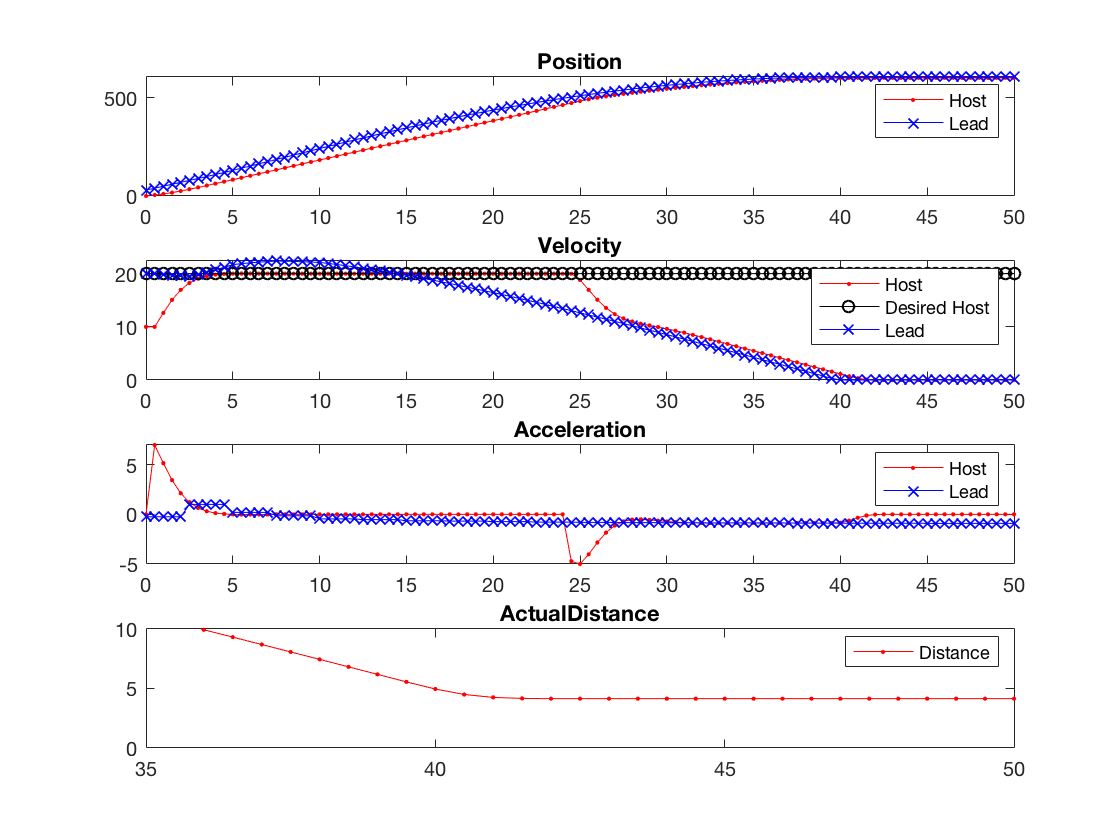

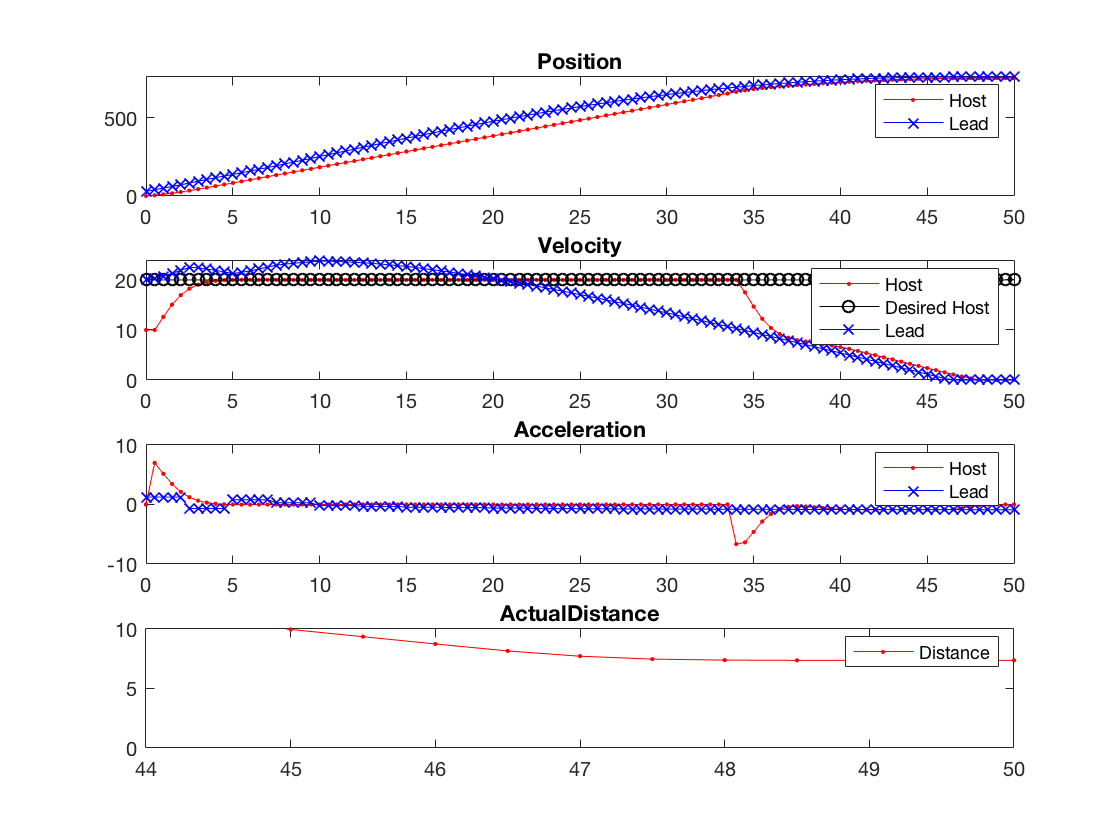

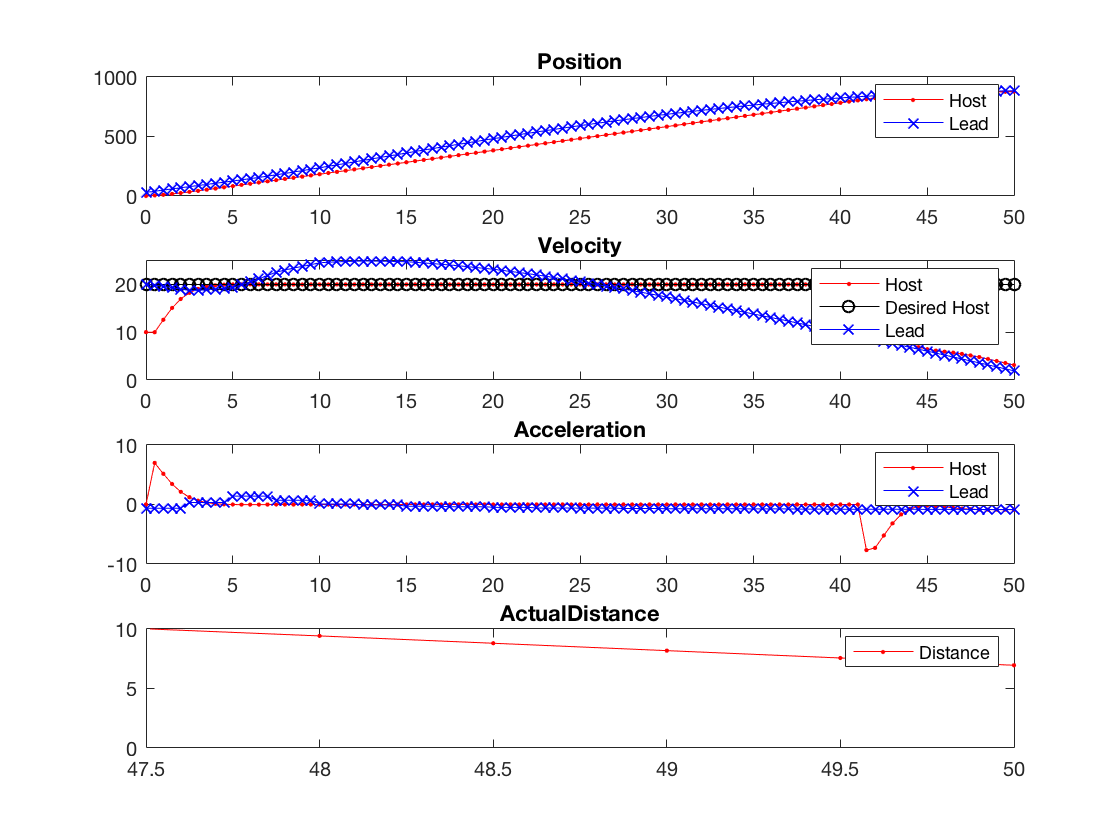

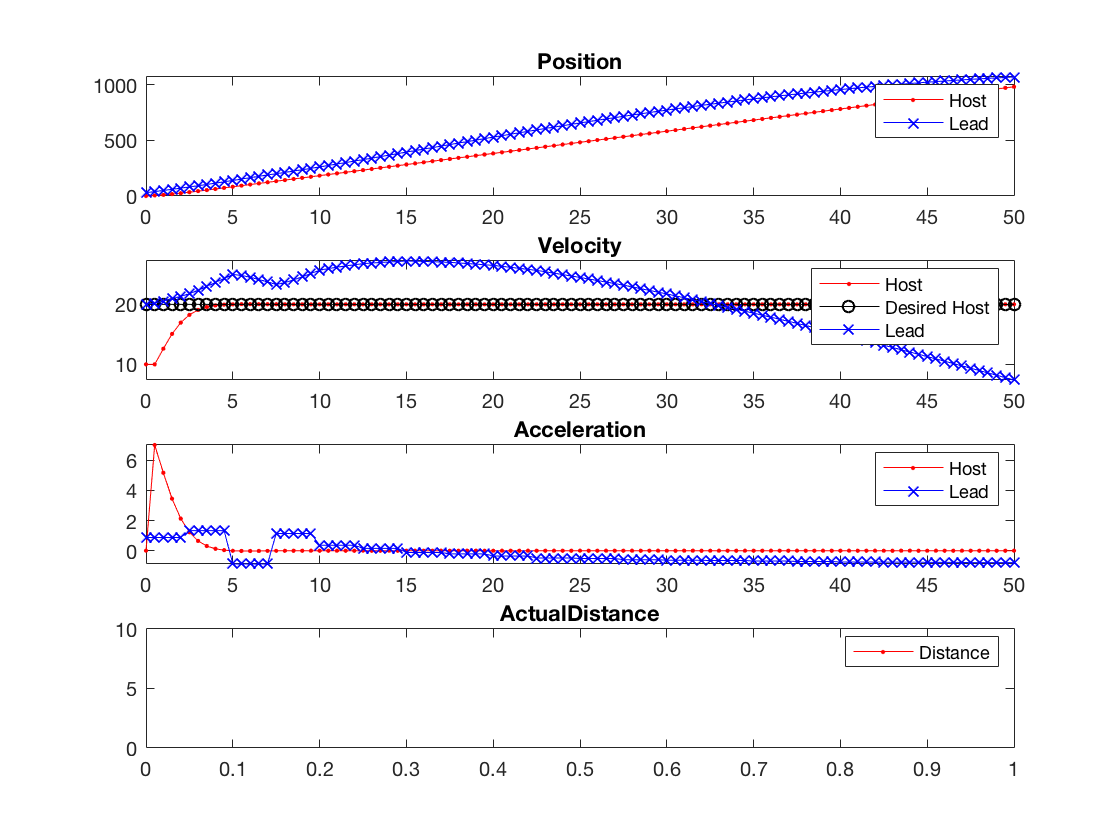

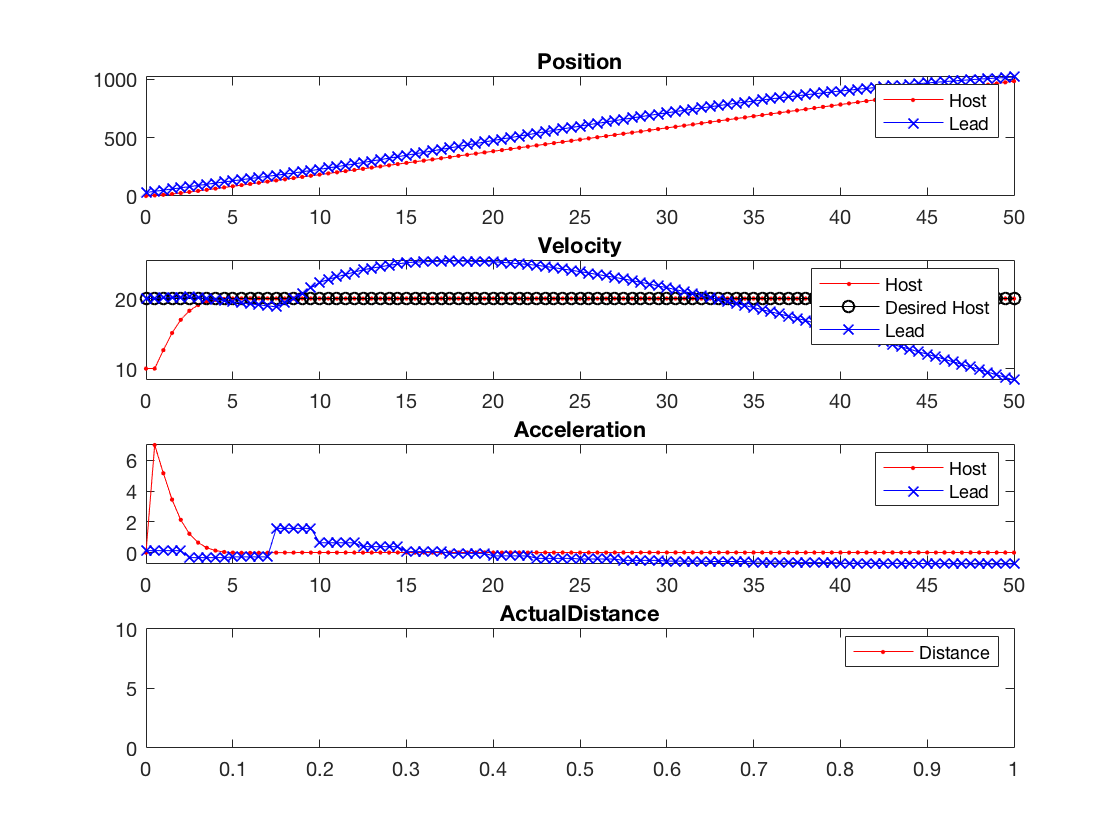

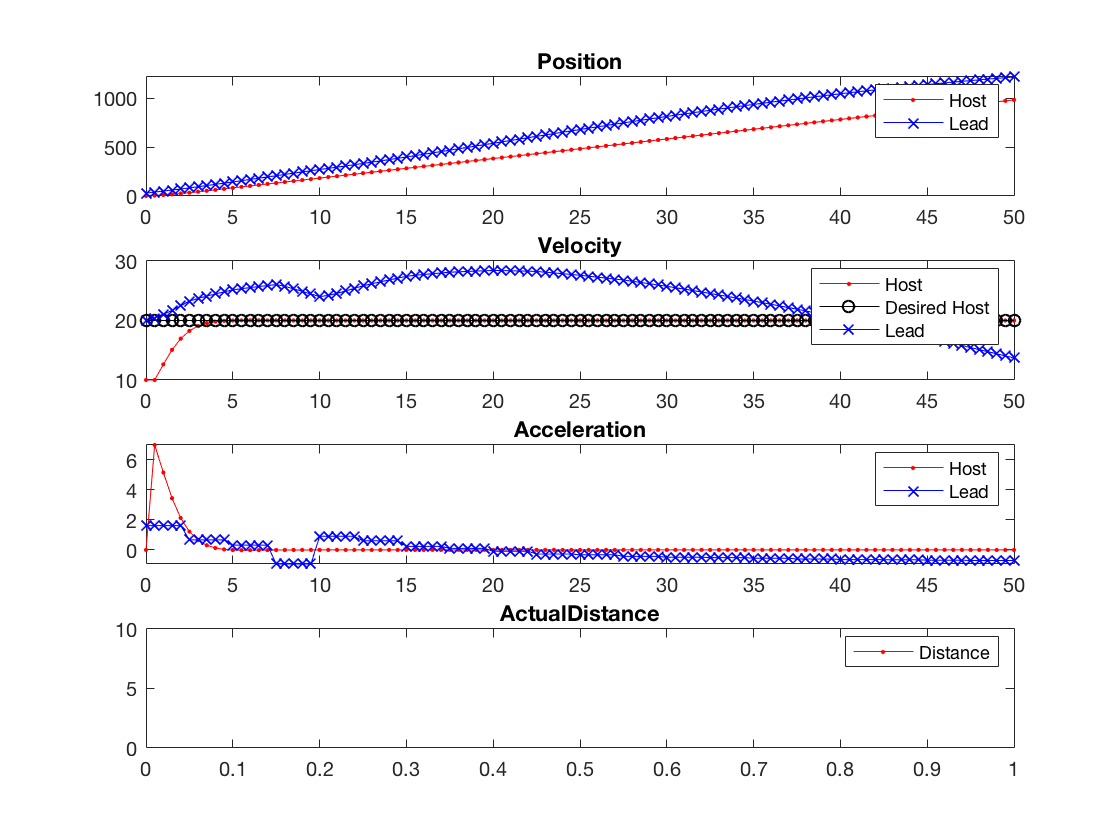

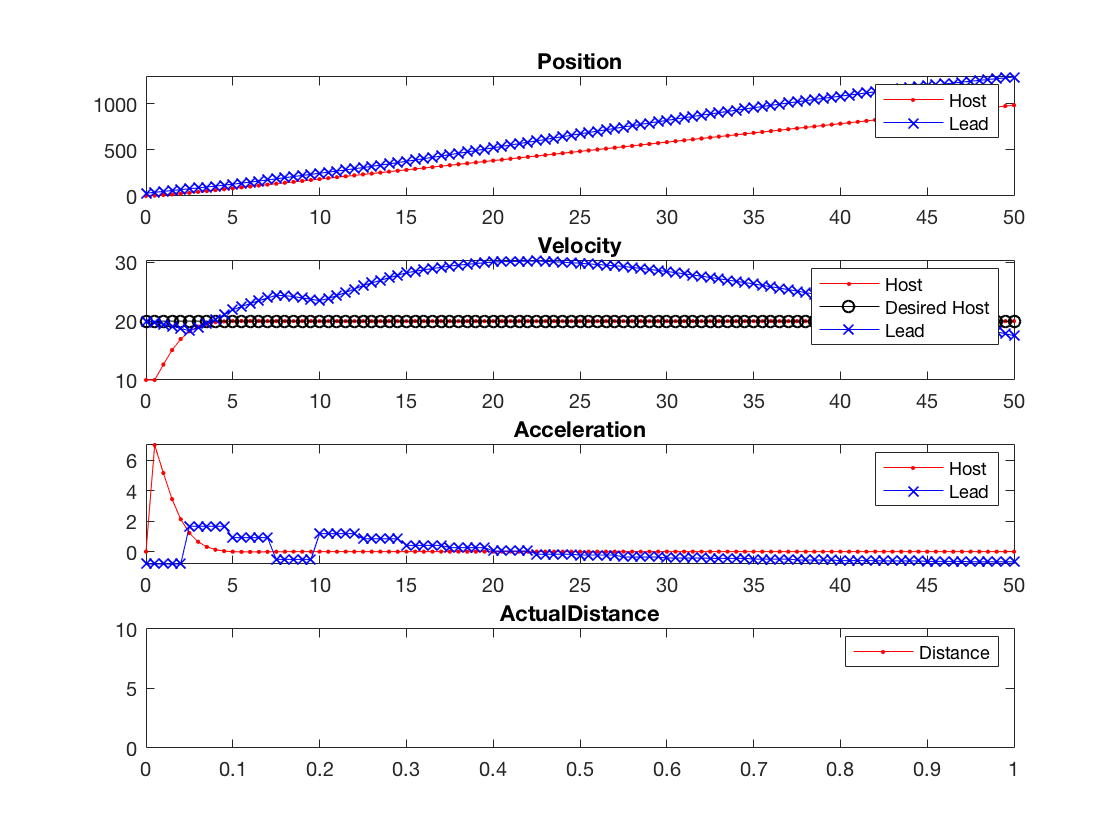

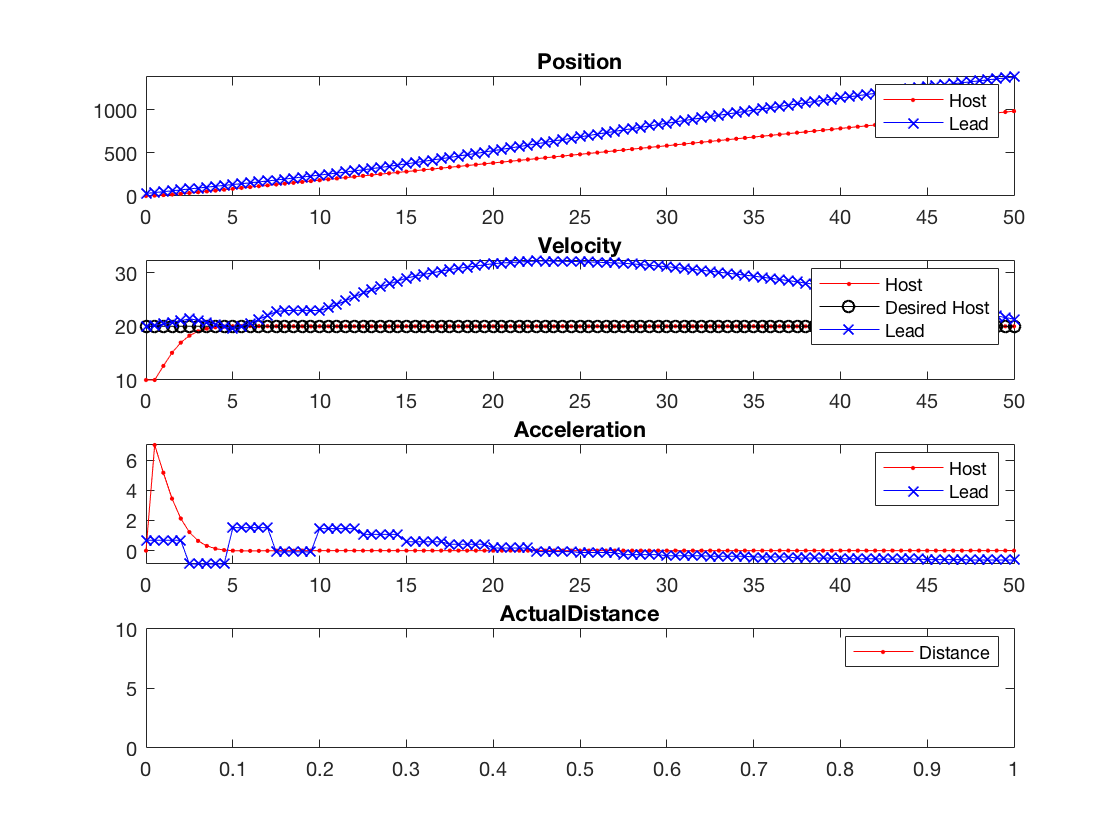

signalValues = S.GetSignalValues({'HostPosition','LeadPosition',...
                               'HostVelocity','LeadAcc',...
                               'HostAcceleration','LeadVelocity',...
                               'ActualDistance'});
close all;

% as a safeguard, you could use min(numSimulations,20) instead of
% numSimulations as the loop termination condition below:
for jj=1:min(numSimulations, 20)
    figure;
    trace = signalValues{jj};
    subplot(4,1,1);
    plot(tspan,trace(1,:),'-r.', tspan, trace(2,:), '-bx');
    % title, legend code courtesy Ryan Blackwell
    title('Position');
    legend('Host','Lead');
    
    subplot(4,1,2);    
    plot(tspan,trace(3,:),'-r.', ...
         tspan, vref_host*ones(1,length(tspan)),'-ko', ... 
         tspan,trace(6,:),'-bx');   
    title('Velocity');
    legend('Host','Desired Host','Lead');
    
    subplot(4,1,3);
    plot(tspan,trace(5,:),'-r.',tspan,trace(4,:),'-bx');
    title('Acceleration');
    legend('Host','Lead');
    
    subplot(4,1,4);
    plot(tspan,trace(7,:),'-r.');
    title('ActualDistance');
    legend('Distance');
    ylim([0, 10])
end